# Plot Eigenvectors

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

This code sets up the activity.

A = [2 2; 5 -1]

A =      2     2
     5    -1


z = [-2; 0]

z =     -2
     0


## Task 1

All vectors have a magnitude and direction. If **z** is

 [−2

0]

, the magnitude of **z** is 2 and the direction is along the negative *x*-axis.

Multiplying a matrix *A* and a vector **z** will create a vector with a new magnitude and direction.

Az = A*z;

## Task 2

The function `plotVectorPair` was created for this course. It accepts two vectors as input and plots them:

`plotVectorPair``(``z``,``Az``)`

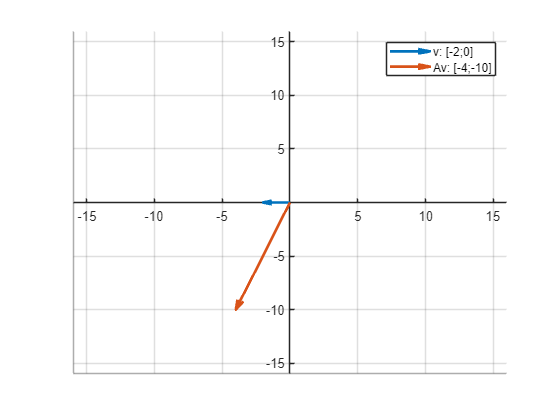

plotVectorPair(z, Az)

## Task 3

Notice how both the magnitude and direction of `z` are changed when it is multiplied by the matrix `A`.

Eigenvectors are unique because multiplying it by *A* will change the magnitude of the vector, but *not* the direction.

The vector 

[2

−5]

 is an eigenvector of *A*.

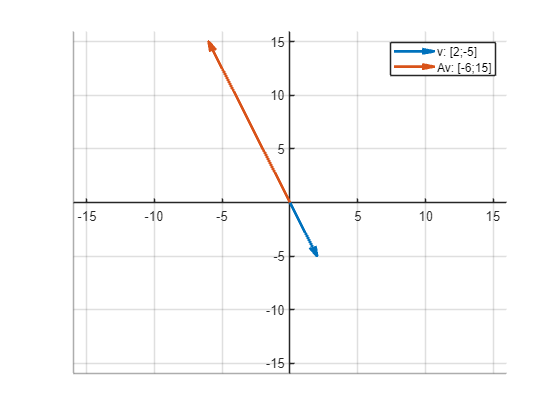

v1 = [2; -5];
Av1 = A*v1;
plotVectorPair(v1, Av1)

function plotVectorPair(vec,Avec)
% Plot the vector vec
quiver(0,0,vec(1),vec(2),'-','MaxHeadSize',3/norm(vec),'AutoScale','off');
% Plot the vector Avec 
hold on
quiver(0,0,Avec(1),Avec(2),'-','MaxHeadSize',3/norm(Avec),'AutoScale','off');
hold off
% Center the axis origin
a = gca;
a.XAxisLocation = 'origin';
a.YAxisLocation = 'origin';
a.Children(1).LineWidth = 2;
a.Children(2).LineWidth = 2;
xlim([-16 16])
ylim([-16 16])
% Remove the box around the axis
box(a,'off')
%Add a grid
grid on
% Add a legend
legend(['v: [',num2str(vec(1)),';',num2str(vec(2)),']'],['Av: [',num2str(Avec(1)),';',num2str(Avec(2)),']'])
end